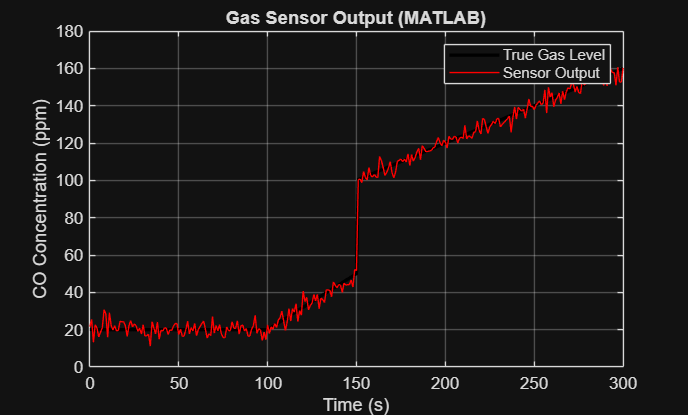

clc; clear; close all;

% Load environment data from Python
data = readtable('C:\Users\aadih\Desktop\desktop\work\semester 4\IOT and Communication\proj_sim\mine_environment.csv');

t = data.time;
gas_true = data.gas_true;

% Sensor noise (MQ sensor behavior)
noise_std = 3; % ppm
sensor_output_1 = gas_true + noise_std * randn(size(gas_true));

% Plot
figure;
plot(t, gas_true, 'k', 'LineWidth', 2); hold on;
plot(t, sensor_output_1, 'r');
legend('True Gas Level', 'Sensor Output');
xlabel('Time (s)');
ylabel('CO Concentration (ppm)');
title('Gas Sensor Output (MATLAB)');
grid on;


% Save sensor output for Python
save('sensor_output.mat', 't', 'sensor_output_1', 'gas_true');
